Data

x = [5  10  15  20  25  30  35  40  45  50]';
y = [17  24  31  33  37  37  40  40  42  41]';

linear fit

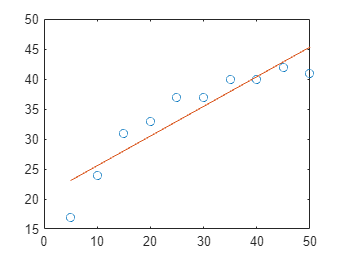

p = polyfit(x,y,1);
xx = 5 : 0.2 : 50;
yy = polyval(p, xx);
plot(x,y,'o',xx,yy,'-')

% linregr(x,y)

% z_linear = [ones(length(x),1) x];
% a_linear = (z_linear'*z_linear) \ (z_linear'*y);
% Sr_linear = sum((y-z*a_linear).^2);
% St_linear = sum((y-mean(y)).^2);
% r2_linear = 1 - Sr_linear/St_linear

Quadratic fit

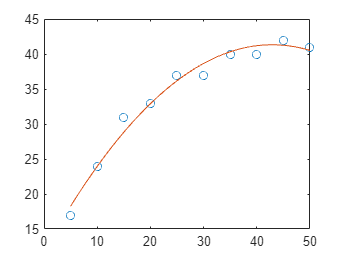

p = polyfit(x,y,2);
xx = 5 : 0.2 : 50;
yy = polyval(p, xx);
plot(x,y,'o',xx,yy,'-')


z = [ones(length(x),1) x x.*x];
a = (z'*z) \ (z'*y);
Sr = sum((y-z*a).^2);
St = sum((y-mean(y)).^2);
r2Quadratic = 1 - Sr/St

r2Quadratic = 0.9800

Cubic fit

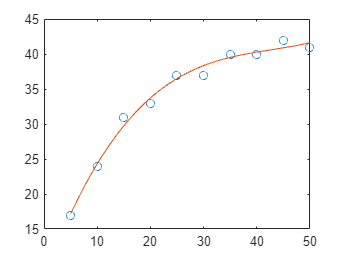

p = polyfit(x,y,3);
xx = 5 : 0.2 : 50;
yy = polyval(p, xx);
plot(x,y,'o',xx,yy,'-')


z_cubic = [ones(length(x), 1), x, x.*x, x.*x.*x];
a_cubic = (z_cubic' * z_cubic) \ (z_cubic' * y);
Sr_cubic = sum((y - z_cubic * a_cubic).^2);
St_cubic = sum((y - mean(y)).^2);
r2Cubic = 1 - Sr_cubic / St_cubic

r2Cubic = 0.9897

A power equation fit

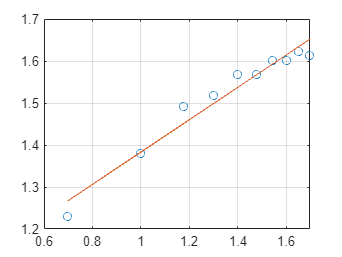

new_x = log10(x);
new_y = log10(y);
[a,r2] = linregr(new_x,new_y);

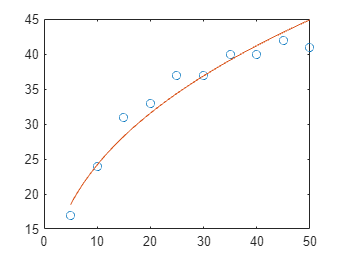

alpha = 10^a(2); 
beta = a(1); 
xx = 5 : 0.2 : 50;
yy = alpha * xx.^beta;
plot(x, y, 'o', xx, yy, '-')


y_predic = alpha * x.^beta;
Sr_power = sum((y - y_predic).^2);
St_power = sum((y - mean(y)).^2);
r2_power = 1 - Sr_power / St_power

r2_power = 0.9377

A saturation-growth-rate equation fit

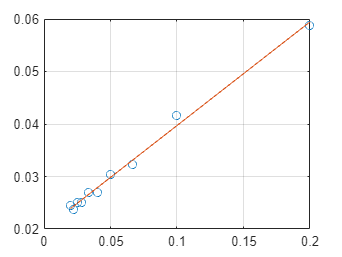

new_xs = 1./x;
new_ys = 1./y;
[a,r2] = linregr(new_xs,new_ys);

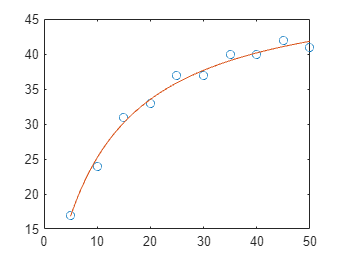

alpha = 1/a(2);
beta = alpha*a(1);
xx = 5 : 0.2 : 50;
yy = alpha * (xx ./ (beta + xx));
plot(x, y, 'o', xx, yy, '-')


y_predic_growth = alpha * (x ./ (beta + x));
Sr_growth = sum((y - y_predic_growth).^2);
St_growth = sum((y - mean(y)).^2);
r2_growth = 1 - Sr_growth / St_growth

r2_growth = 0.9892